% MATLAB Code | Ideal Low Pass Filter
input_image = imread('Brain MRI.png');
[M, N] = size(input_image);
FT_img = fft2(double(input_image));
D0 = 30;
u = 0:(M-1);
idx = find(u>M/2);
u(idx) = u(idx)-M;
v = 0:(N-1);
idy = find(v>N/2);
v(idy) = v(idy)-N;
[V, U] = meshgrid(v, u);
D = sqrt(U.^2+V.^2);
H = double(D <= D0);
G = H.*FT_img;
output_image = real(ifft2(double(G)));
subplot(2, 2, 1), imshow(input_image), title('Original Image');
subplot(2, 2, 2), imshow(output_image, [ ]), title('After LPF');


% MATLAB Code | Ideal High Pass Filter

input_image = imread('Brain MRI.png');
[M, N] = size(input_image);
FT_img = fft2(double(input_image));
D0 = 10; 
u = 0:(M-1);
idx = find(u>M/2);
u(idx) = u(idx)-M;
v = 0:(N-1);
idy = find(v>N/2);
v(idy) = v(idy)-N;
[V, U] = meshgrid(v, u);
D = sqrt(U.^2+V.^2);
H = double(D > D0);
G = H.*FT_img;
output_image = real(ifft2(double(G)));
subplot(2, 2, 1), imshow(input_image), title('Original Image');
subplot(2, 2, 2), imshow(output_image, [ ]), title('After LHF');

% MATLAB Code | Butterworth Low Pass Filter

input_image = imread('Brain MRI.png');
[M, N] = size(input_image);
FT_img = fft2(double(input_image));
n = 2; 
D0 = 20; 
u = 0:(M-1);
v = 0:(N-1);
idx = find(u > M/2);
u(idx) = u(idx) - M;
idy = find(v > N/2);
v(idy) = v(idy) - N;
[V, U] = meshgrid(v, u);
D = sqrt(U.^2 + V.^2);
H = 1./(1 + (D./D0).^(2*n));
G = H.*FT_img;
output_image = real(ifft2(double(G)));
subplot(2, 2, 1), imshow(input_image), title('Original Image');
subplot(2, 2, 2), imshow(output_image, [ ]), title('After BLF');


% MATLAB Code | Butterworth High Pass Filter
	
input_image = imread('Brain MRI.png');
[M, N] = size(input_image);
FT_img = fft2(double(input_image));
n = 2; 
D0 = 10;
u = 0:(M-1);
v = 0:(N-1);
idx = find(u > M/2);
u(idx) = u(idx) - M;
idy = find(v > N/2);
v(idy) = v(idy) - N;
[V, U] = meshgrid(v, u);
D = sqrt(U.^2 + V.^2);
H = 1./(1 + (D0./D).^(2*n));
G = H.*FT_img;
output_image = real(ifft2(double(G)));
subplot(2, 2, 1), imshow(input_image), title('Original Image');
subplot(2, 2, 2), imshow(output_image, [ ]), title('After BHF');

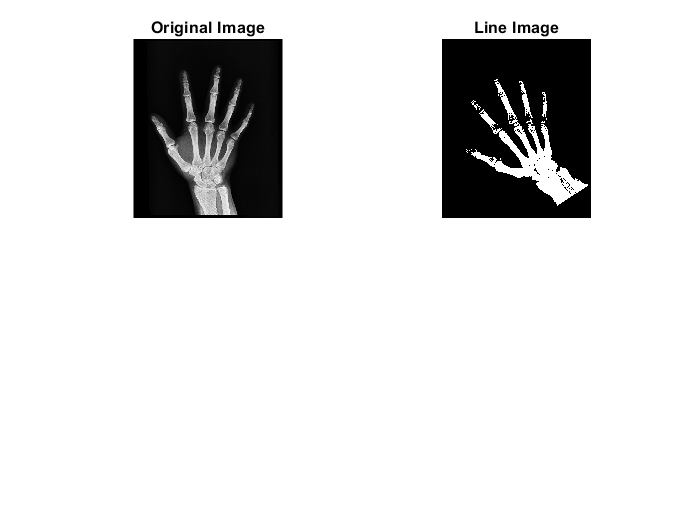

% MATLAB Code | Line Detection
	
img  = imread('X-Ray Image.png');
I = im2bw(img);
rotI = imrotate(I,33,'crop');
fig1 = imshow(rotI);

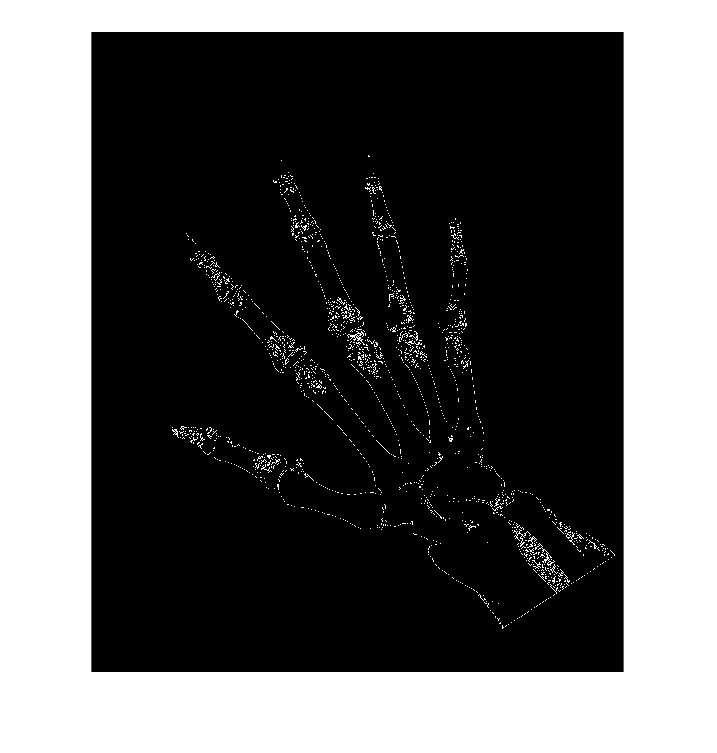

BW = edge(rotI,'canny');
figure, imshow(BW);

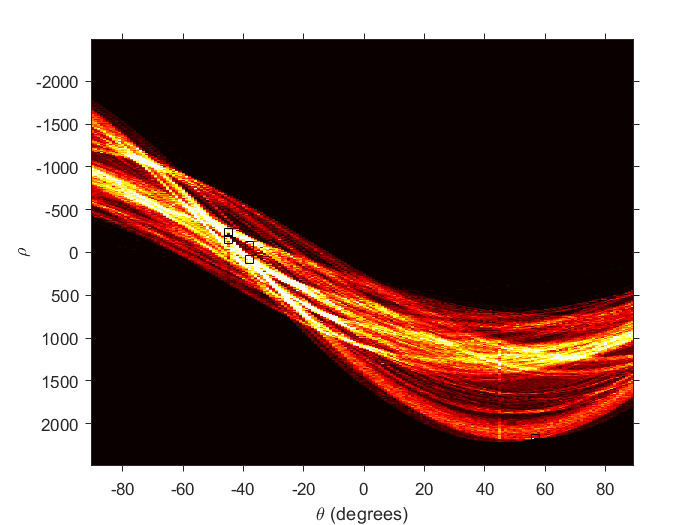

[H,theta,rho] = hough(BW);
figure, imshow(imadjust(mat2gray(H)),[],'XData',theta,'YData',rho,...
        'InitialMagnification','fit');
xlabel('\theta (degrees)'), ylabel('\rho');
axis on, axis normal, hold on;
colormap(hot)
P = houghpeaks(H,5,'threshold',ceil(0.3*max(H(:))));
x = theta(P(:,2));
y = rho(P(:,1));
plot(x,y,'s','color','black');

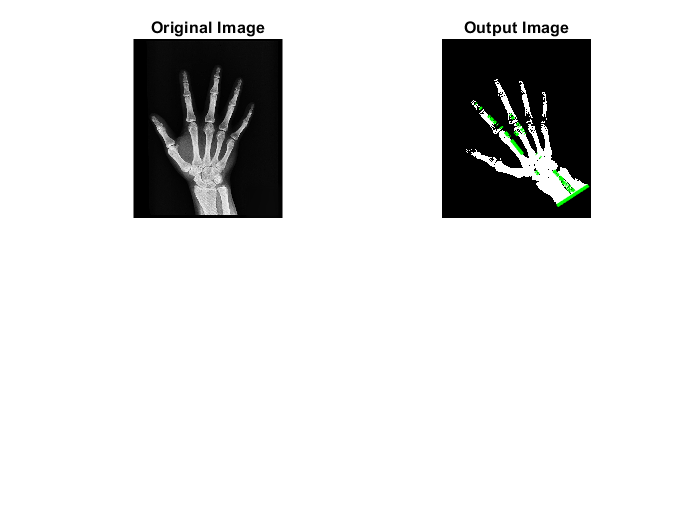

lines = houghlines(BW,theta,rho,P,'FillGap',5,'MinLength',7);

subplot(2, 2, 1), imshow(img), title('Original Image');
subplot(2, 2, 2), imshow(rotI),title('Output Image'), hold on
max_len = 0;
for k = 1:length(lines)
   xy = [lines(k).point1; lines(k).point2];
   plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');
end

% MATLAB Code | Gaussian low pass filtering of an image

img  = imread('Brain MRI.png');
[m, n] = size(img);

fc = 10;
p = round(m/2);
q = round(n/2);

H = zeros(m,n);
for i = 1:m
    for j = 1:p
        d  = (i-p).^2 + (j-q).^2;
        H(i, j) = exp(-d/2/fc/fc);
    end
end

A_f = fftshift(fft2(img));

B = A_f.*H;
C = abs(ifft2(B));
glpf = uint8(C);
subplot(2, 2, 1), imshow(img), title('Original Image');
subplot(2, 2, 2), imshow(glpf), title('After GLPF');


% MATLAB Code | Gaussian high pass filtering of an image

img  = imread('Brain MRI.png');
[m, n] = size(img);
fc = 10;
p = round(m/2);
q = round(n/2);
H = zeros(m,n);
for i = 1:m
    for j = 1:p
        d  = (i-p).^2 + (j-q).^2;
        H(i, j) = exp(-d/2/fc/fc);
    end
end
H = 1-H;
A_f = fftshift(fft2(img));
B = A_f.*H;
C = abs(ifft2(B));
ghpf = uint8(C);
subplot(2, 2, 1), imshow(img), title('Original Image');
subplot(2, 2, 2), imshow(ghpf), title('After GHPF');